data = load("resultadosCSV_2m_6.txt");
length(data)

ans =         1024



stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start =     27


n_max_start = 335

n_max_start =    335


T           = 5e-9;

% tau = mean([tau_stop, tau_start])
tau = tau_stop

tau =      1.572000000000000e-11



T_buscado = 1/(2*2e6)

T_buscado =      2.500000000000000e-07


T_buscado/T

ans =     50


tiempo_muerto = 15*5e-9

tiempo_muerto =      7.500000000000000e-08


st = start-stop;
indices_st = find(st>0);
indices_st_neg = find(st<0);
st(indices_st_neg) = st(indices_st_neg) + (n_max_start-n_min_start);
st_positivo = st(indices_st);
std(st_positivo)

ans =    1.338645280182885


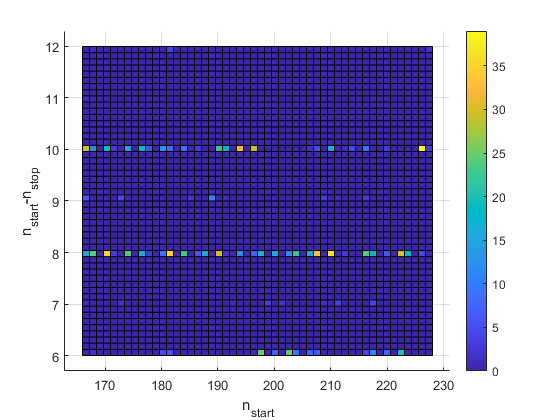

hist3([start, st], 'CdataMode','auto', 'Nbins',[50 50])
view(2); colorbar; ylabel('n_{start}-n_{stop}'); xlabel('n_{start}')
exportgraphics(gcf,'start-stop_2M_ultimaprueba.eps');